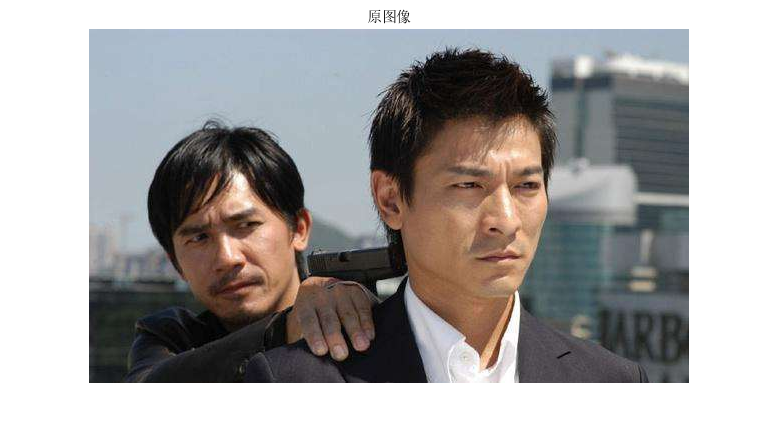

clc;
clear;
I=imread("06-刘德华.jpg");
figure
imshow(I);
title("原图像");

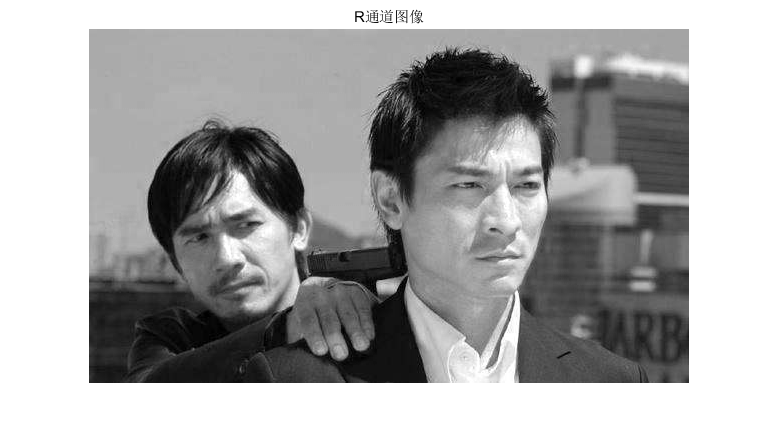

I_R=I(:,:,1);
figure
imshow(I_R);
title("R通道图像");

%实现空间平滑滤波，进行均值滤波
%滤波算子为：[1/9 1/9 1/9
%             1/9 1/9 1/9
%             1/9 1/9 1/9]
%创建滤波算子
h_mean=fspecial('average',3)

h_mean =     0.1111    0.1111    0.1111
    0.1111    0.1111    0.1111
    0.1111    0.1111    0.1111


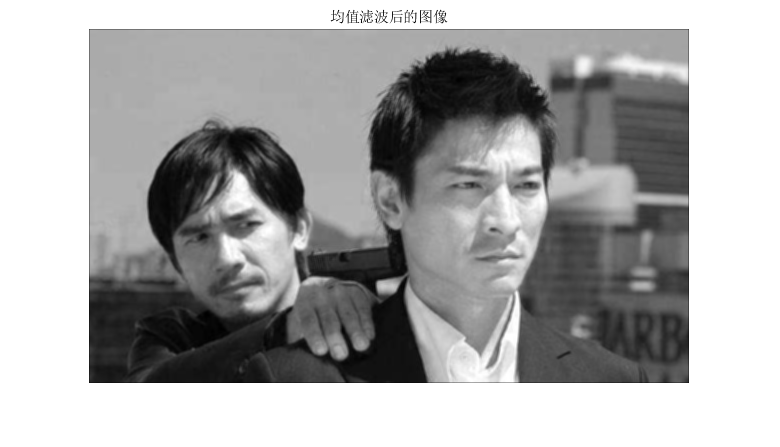

%均值滤波
I_mean=filter2(h_mean,I_R);
fig1=figure;
imshow(I_mean,[]);
title("均值滤波后的图像");
%储存
saveas(fig1,'均值滤波后的图片.jpg','jpg');

%锐化
%拉普拉斯算子为 [ -1  -1  -1
%                 -1   8  -1
%                 -1  -1  -1 ]
h_laplace=-[1 1 1;1 -8 1;1 1 1]

h_laplace =     -1    -1    -1
    -1     8    -1
    -1    -1    -1


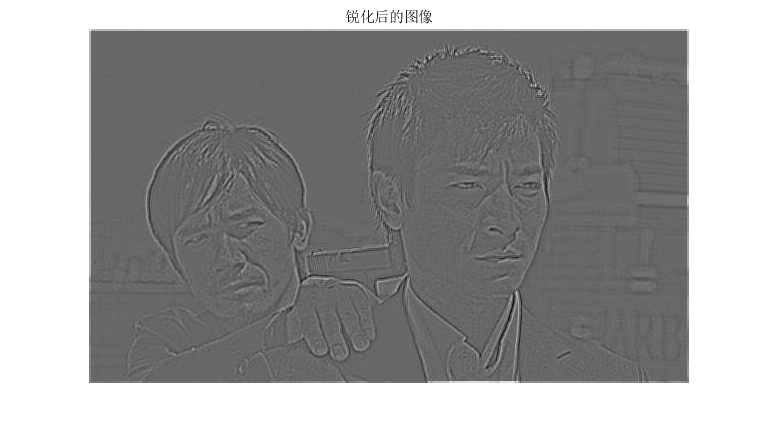

I_laplace=filter2(h_laplace,I_mean);
fig2=figure;
imshow(I_laplace,[]);
title("锐化后的图像");
%储存
saveas(fig2,'锐化后的图片.jpg','jpg');